TEST NAVIGAZIONE CON CON PUNTI DATI CON PID E IMU

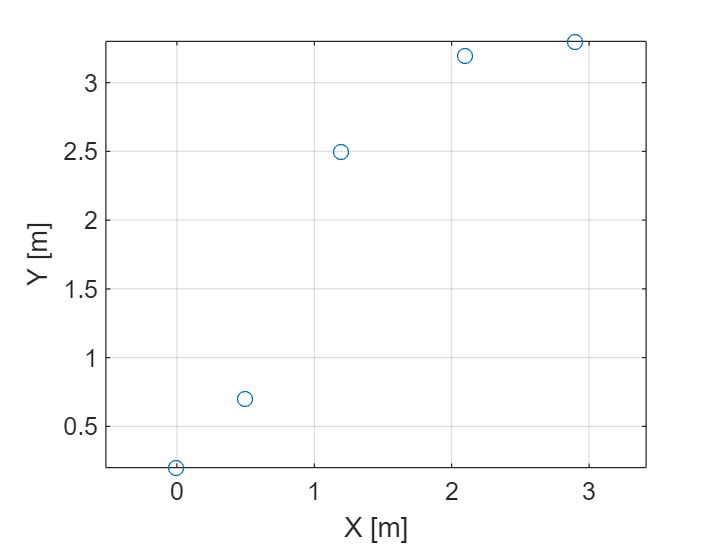

clc;
clear;
clear all;
clf;
rrt_relative_tree = [0, 0.5, 1.2, 2.10, 2.9; 0.2, 0.7, 2.5, 3.2, 3.3];
figure();
plot(rrt_relative_tree(1, :), rrt_relative_tree(2, :),'o');
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');

IMU = imuSensor('IMUType','accel-gyro')

IMU =   imuSensor with properties:

          IMUType: 'accel-gyro'
       SampleRate: 100
      Temperature: 25
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     RandomStream: 'Global stream'


% 

SpecSheet1 = accelparams( ...
    'MeasurementRange',20, ...
    'Resolution',0.001, ...
    'ConstantBias',0.5, ...
    'AxesMisalignment',2, ...
    'NoiseDensity',0.01, ...
    'BiasInstability',0);

IMU.Accelerometer = SpecSheet1;

IMU.Accelerometer

ans =   accelparams with properties:

    MeasurementRange: 20               m/s²      
          Resolution: 0.001            (m/s²)/LSB
        ConstantBias: [0.5 0.5 0.5]    m/s²      
    AxesMisalignment: [3⨯3 double]     %         

                   NoiseDensity: [0.01 0.01 0.01]    (m/s²)/√Hz
                BiasInstability: [0 0 0]             m/s²      
                     RandomWalk: [0 0 0]             (m/s²)*√Hz
                      NoiseType: "double-sided"                
    BiasInstabilityCoefficients: [1⨯1 struct]                  

           TemperatureBias: [0 0 0]    (m/s²)/°C
    TemperatureScaleFactor: [0 0 0]    %/°C     




% Coefficienti PID -- METTERE IN FUNZIONE
Kp = 0.6; % componente proporzionale
Ki = 0.02; % componente integrale
Kd = 0.9; % componente derivativa

% Error variables
error_sum=0;
previous_error = 0;

final_pos = rrt_relative_tree(:, length(rrt_relative_tree));
% Velocità iniziale e finale desiderate
initial_vel = [0; 0];
max_speed = [1; 1]; % velocità massima consentita
final_vel = max_speed/2; % velocità finale desiderata
max_acc = 1; % [m/s^2] max acceleration
% Simulazione del controllo PID
t = 0; % tempo iniziale
positions = []; % registro delle posizioni per la visualizzazione
% Passo temporale (in secondi)
dt = 0.1;

% Posizione iniziale del punto
pos = rrt_relative_tree(:, 1);

% Velocità iniziale del punto
vel = initial_vel;

% continua finché non si raggiunge la destinazione

proximity_threshold = 0.1;
figure();
for i=2:length(rrt_relative_tree)

    % momentaneous target of the drone where it has to go
    final_pos = rrt_relative_tree(:, i);

    while norm(pos - final_pos) > proximity_threshold  
        % Calcolo dell'errore di posizione
        error_pos = final_pos - pos;

        % Componente proporzionale
        control_p = Kp * error_pos;

        % Componente integrale
        error_sum = error_sum + error_pos * dt;
        control_i = Ki * error_sum;

        % Componente derivativa
        derivative = (error_pos - previous_error) / dt;
        control_d = Kd * derivative;

        % Controllo finale
        control = control_p + control_i + control_d;

        % Limitazione della velocità
        control = min(max(control, -max_acc), max_acc);
        
        control_imu_acc = [control', 0];
        control_imu_gyro = [0 0 0];
        % Aggiornamento della velocità e della posizione
        
        [accelReading,~] = IMU(control_imu_acc,control_imu_gyro)
        

        vel = vel + accelReading(1:2) * dt;
        pos = pos + vel * dt;

        % Memorizzazione della posizione
        positions = [positions, pos];

        % Aggiornamento dell'errore precedente
        previous_error = error_pos;

        t = t + dt; % incremento del tempo
        pause()
    end

    %Visualize the time requested and error
    % t
    % vel(length(vel))
    % pos(length(pos))
    % error_pos(length(error_pos))
    plot(positions(1, length(positions)), positions(2, length(positions)), 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'black');
    hold on;
    %plot the end point
end

accelReading =    -0.2630   -0.3010   10.1780




plot(points(1, :), points(2, :), 'o', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'black')
grid on;
axis equal; 

% Visualizzazione del percorso
%starting point in red
plot(positions(1, 1), positions(2, 1), 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'black');
%plot the path
plot(positions(1, :), positions(2, :), '.', 'Color', 'black');
%ending point in black


xlabel('X [m]');
ylabel('Y [m]');
title('PID test track');
hold off
legend('RRT target points', 'Actual target reached');






% % Call IMU with the ground-truth acceleration and angular velocity. The object outputs accelerometer readings, gyroscope readings, and magnetometer readings, as modeled by the properties of the imuSensor System object. The accelerometer readings, gyroscope readings, and magnetometer readings are relative to the IMU sensor body coordinate system. 
% [accelReading,gyroReading] = IMU(acceleration,angularVelocity);
% 
% % Plot the accelerometer readings, gyroscope readings, and magnetometer readings.
% t = (0:(numSamples-1))/IMU.SampleRate;
% subplot(2,1,1)
% plot(t,accelReading)
% legend('X-axis','Y-axis','Z-axis')
% title('Accelerometer Readings')
% ylabel('Acceleration (m/s^2)')
% 
% subplot(2,1,2)
% plot(t,gyroReading)
% legend('X-axis','Y-axis','Z-axis')
% title('Gyroscope Readings')
% ylabel('Angular Velocity (rad/s)')
% 
% 
% % Orientation is not specified and the ground-truth motion is stationary, so the IMU sensor body coordinate system and the local NED coordinate system overlap for the entire simulation.
% % Accelerometer readings: The z-axis of the sensor body corresponds to the Down-axis. The 9.8 m/s^2 acceleration along the z-axis is due to gravity.
% % Gyroscope readings: The gyroscope readings are zero along each axis, as expected.
% % Magnetometer readings: Because the sensor body coordinate system is aligned with the local NED coordinate system, the magnetometer readings correspond to the MagneticField property of imuSensor. The MagneticField property is defined in the local NED coordinate system.
% % Copyright 2018 The MathWorks, Inc.
% 